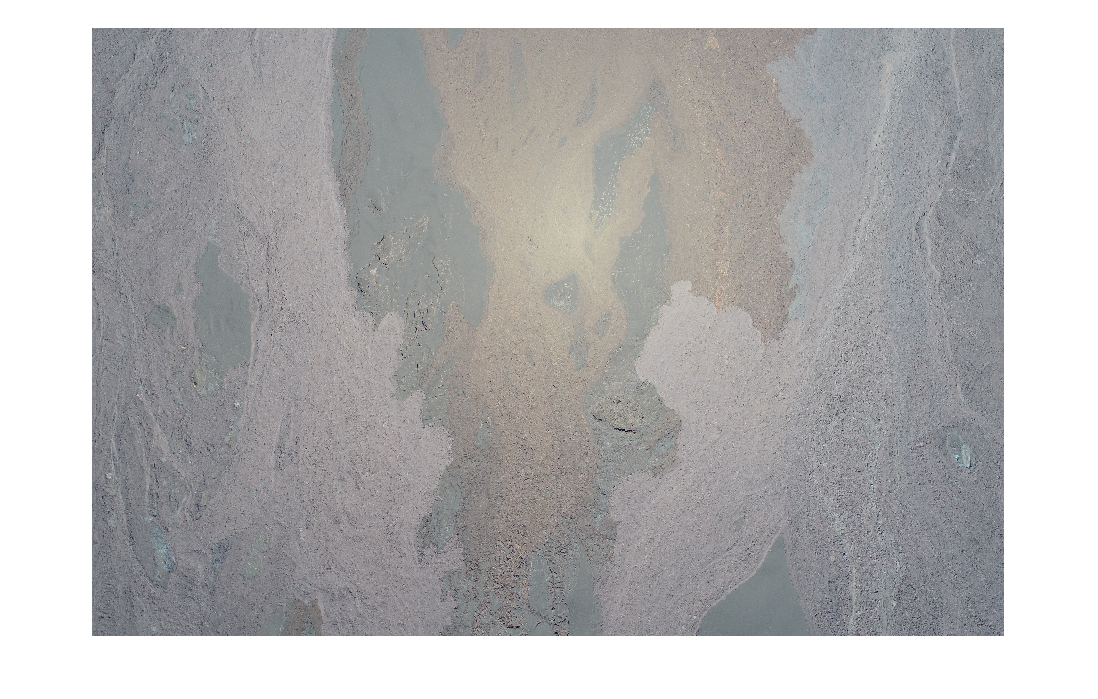

addpath (genpath('/home/johnpaustian/matlab/ClassifyImages'));

addpath (genpath('/home/johnpaustian/scratch/Imagery'));

i = imread('GAL010_00142.JPG');

imshow(i)


imwrite(i,'image1.tif')

% Run GUI

RUN_GUI

clear all

load image1_GTOutput_20190726T104846.mat; % load from home

imwrite(output.groundTruth.matrix,'groundtruth.tif','tiff')


inputs.IMAGE = 'image1.tif';
inputs.GRNDTRUTH = 'groundtruth.tif';
inputs.nclasses  = 4;    % number of classes
inputs.crossval  = 1;    % 1 = k-fold cross validation; 0,[] = none.
inputs.thresh    = [];   % 100,[] = no threshold; alph = alpha% chi^2 c.i.
inputs.prefilt   = 1;    % [] or 0 = no prefilt, 1 = 1st, 2 = 2nd, 3 = 3rd 
                         % order neighborhoods
inputs.smoothing = 3;    % 0,[] = none; 1 = nonlin filter; 2 = PLR; 3 = MRF
inputs.iter      = 5;    % # iters in PLR or MRF.
inputs.beta      = 10;   % beta (regularization parameter) for MRF.

tic
outputs = ImageClassify(inputs);

10 PERCENT RANDOM REMOVAL CROSS VALIDATION.
Percent misclassified after 10 removals = 5.5687
MRF iter = 1
MRF iter = 2
MRF iter = 3
MRF iter = 4
MRF iter = 5


toc

Elapsed time is 33.428844 seconds.


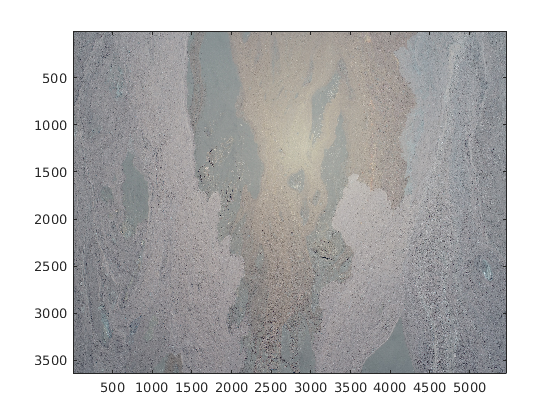

Image = outputs.Image;
GrndTruth = outputs.GrndTruth;
Classification = outputs.Classification;

if isempty(inputs.thresh)==1
    inputs.thresh = -1;
end
if 0<inputs.thresh && inputs.thresh<100
    inputs.nclasses=inputs.nclasses+1;
end

i = figure;
    imagesc(Image)

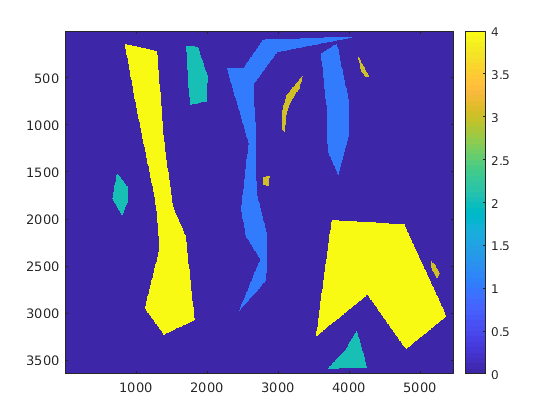

gt = figure;
    imagesc(GrndTruth)
    colorbar, caxis([0,inputs.nclasses]) 

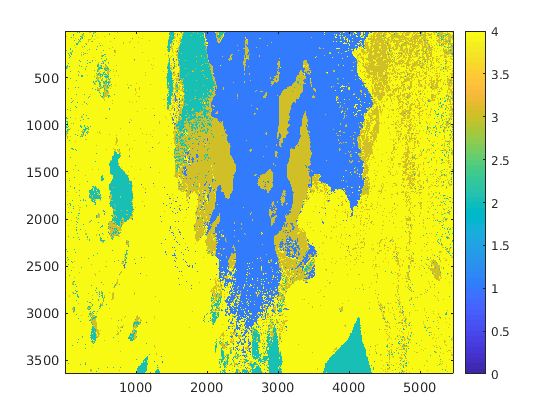

classify = figure;
    imagesc(Classification)
    colorbar, caxis([0,inputs.nclasses]) 

% save supervised classification to file

save('spv_class.mat','Classification');

% Testing a pixel classification

%create ground truth data source from image file

%test = imread('GAL010_00142.JPG')

%gtSource = groundTruthDataSource('GAL010_00142.JPG');

%Define labels used to specify ground truth

defs = table({'OldLava';'Scoria';'Pahoehoe';'Aa'}, ...
	[labelType.PixelLabel;labelType.PixelLabel;labelType.PixelLabel;labelType.PixelLabel], ...
 ['1';'2';'3';'4'], ...
	'VariableNames',{'Name','Type','PixelLabelID'})

defs = 4×3 table
       Name          Type       PixelLabelID
    __________    __________    ____________

    'OldLava'     PixelLabel         1      
    'Scoria'      PixelLabel         2      
    'Pahoehoe'    PixelLabel         3      
    'Aa'          PixelLabel         4      




%create a groundtruth object from gTruth_spv

gTruth_spv = groundTruth(test,defs,'spv_class.mat')  %% start here, use galLabels for pixel labels

Undefined function or variable 'test'.


%create pixel label datastore

%pxds = pixelLabelDatastore('spv_class')
